**Student Name:    _ _ _ _ _ _ _ _ _ _ _ _ _ **

**H-ID:                    _ _ _ _ _ _ _ _ _ _ _ _ _ **

# **Open Loop & Closed Loop System**

The open-loop transfer function model of the DC Motor is repeated below.


$$  P(s) = \frac{\dot{\Theta}(s)}{V(s)} = \frac{K}{(Js + b)(Ls + R) + K^2}  \qquad  [ \frac{rad/sec}{V} ] $$


The structure of the control system has the form shown in the figure below.

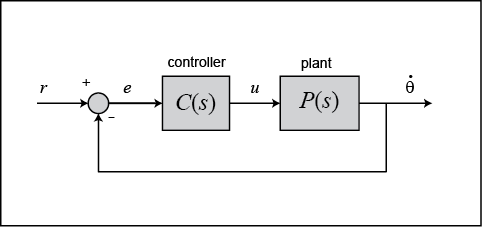

The original parameters used in this example are as follows: 

For a 1-rad/sec step reference, the design criteria are the following.

## In-Lab Task 

Develop MATLAB codes to simulate the system step response for the given default parameters. 

## Defining Input Variables

clc;
clear;

% define input variables
J = 0.01;
b = 0.1;
Ke = 0.01;
Kt = 0.01;
R = 1;
L = 0.5;

K = [1 10 30];      % gain controller

% create a open loop transfer function
s = tf('s');

Ps = Kt / ((J*s + b)*(L*s +R) + Kt^2)

Ps =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


## Open Loop Analysis

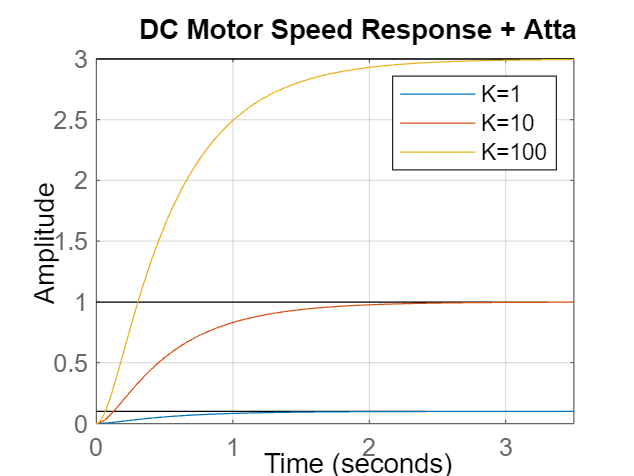

% analyze the open loop step response with different values of gain
% transient response of the system
step(K(1)*Ps)
grid on;
title('DC Motor Speed Response + Atta')
hold on;
step(K(2)*Ps)
step(K(3)*Ps)
legend('K=1', 'K=10','K=100')
hold off;

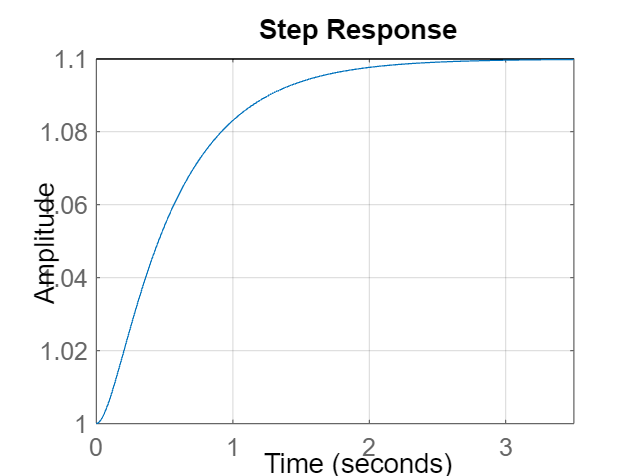



% analyze the effect of disturbance on open loop response with different
% values of gain
% transient response of the system
Ds = 1;
step(K(1)*Ps+Ds)
grid on;

## Close Loop Analysis

Generate the Step Response of closed loop system

**Hint:**

`sys = `[`feedback`](https://www.mathworks.com/help/releases/R2020a/control/ref/feedback.html)`(sys1,sys2)` returns a model object `sys` for the negative feedback interconnection of model objects `sys1,sys2`.

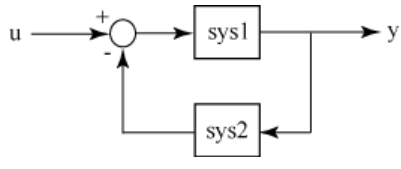

% analyze the close loop step response with different values of gain
% transient response of the system
cl_1 = feedback(K(1)*Ps, 1)

cl_1 =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1101
 
Continuous-time transfer function.
Model Properties


step(cl_1)
hold on;
grid on;
cl_10 = feedback(K(2)*Ps, 1)

cl_10 =
 
              0.1
  ---------------------------
  0.005 s^2 + 0.06 s + 0.2001
 
Continuous-time transfer function.
Model Properties


step(cl_10)
cl_30 = feedback(K(3)*Ps, 1)

cl_30 =
 
              0.3
  ---------------------------
  0.005 s^2 + 0.06 s + 0.4001
 
Continuous-time transfer function.
Model Properties


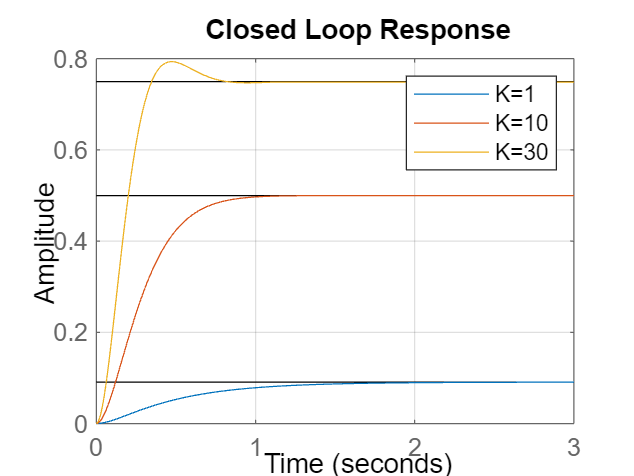

step(cl_30)

title('Closed Loop Response')
legend('K=1', 'K=10', 'K=30')
hold off;




% analyze the effect of disturbance on close loop response with different
% values of gain
% transient response of the system
cl_D = feedback((K(3)*Ps+Ds), 1)

cl_D =
 
  0.005 s^2 + 0.06 s + 0.4001
  ---------------------------
  0.01 s^2 + 0.12 s + 0.5002
 
Continuous-time transfer function.
Model Properties


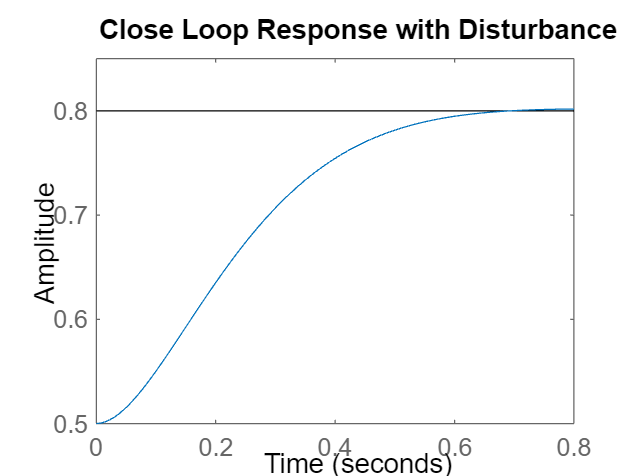

step(cl_D)
title('Close Loop Response with Disturbance')

## Observations

Complete the observations in the Lab Sheet